# A Estimation curve VS different S_EI

## first, setup connctivity map

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;

% Replace S_EI by testing values
S_EItest = 0.054:0.001:0.068;

## Test different stepsizes and LIF simu time

% defining cluster. Stepsizes and simu time I want to test
cluster = parpool([4 64]);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


cluster.IdleTimeout = 120;

htest = [1,0.5,0.1];
SimuTtest = [40 20 10]*1e3; % in ms

a = length(S_EItest);
b = length(htest);
c = length(SimuTtest);

Fr_NoFix_h_time = zeros(2,a,b,c);
mV_NoFix_h_time = zeros(2,a,b,c);
Fr_NoFixVar_h_time = zeros(2,a,b,c);
mV_NoFixVar_h_time = zeros(2,a,b,c);
Fr_NoFixTraj_h_time = cell(a,b,c);
mV_NoFixTraj_h_time = cell(a,b,c);

loopCount_h_time = zeros(a,b,c); % count the number of loops
ConvIndi_h_time = logical(loopCount_h_time);

SampleNum = 200;
MaxNum = 400;
%h = 0.1;
tic
for hInd = 1:b
    h = htest(hInd);
    for SimuTInd = 1:c
        SimuT = SimuTtest(SimuTInd);
        parfor S_EIInd = 1:length(S_EItest)
            S_EI = S_EItest(S_EIInd);
            tic
            [Fr_NoFixTraj_h_time{S_EIInd,hInd,SimuTInd},mV_NoFixTraj_h_time{S_EIInd,hInd,SimuTInd},...
                loopCount_h_time(S_EIInd,hInd,SimuTInd),    ConvIndi_h_time(S_EIInd,hInd,SimuTInd)]...
                ...
                  = MeanFieldEst_BkGd_Indep_StepSize(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,...
                                            'End',SampleNum,MaxNum,h,SimuT);
                                        
            toc
       end
    end
end

Elapsed time is 18.942904 seconds.
Elapsed time is 18.372896 seconds.
Elapsed time is 19.502549 seconds.
Elapsed time is 19.055898 seconds.
Elapsed time is 20.854321 seconds.
Elapsed time is 20.778991 seconds.
Elapsed time is 17.260212 seconds.
Elapsed time is 17.690274 seconds.
Elapsed time is 17.447996 seconds.
Elapsed time is 17.299530 seconds.
Elapsed time is 20.025000 seconds.
Elapsed time is 18.883571 seconds.
Elapsed time is 9.978786 seconds.
Elapsed time is 11.152676 seconds.
Elapsed time is 9.753125 seconds.
Elapsed time is 8.869671 seconds.
Elapsed time is 8.986248 seconds.
Elapsed time is 10.371591 seconds.
Elapsed time is 10.263397 seconds.
Elapsed time is 12.515687 seconds.
Elapsed time is 11.604012 seconds.
Elapsed time is 9.863344 seconds.
Elapsed time is 9.989192 seconds.
Elapsed time is 11.739874 seconds.
Elapsed time is 9.342402 seconds.
Elapsed time is 11.397334 seconds.
Elapsed time is 11.408578 seconds.
Elapsed time is 6.835491 seconds.
Elapsed time is 8.281378 sec

toc

Elapsed time is 288.738684 seconds.



% mean and var
for hInd = 1:b
    for SimuTInd = 1:c
for S_EIInd = 1:length(S_EItest)
    Fr_NoFix_h_time(:,S_EIInd,hInd,SimuTInd) = mean(Fr_NoFixTraj_h_time{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),2);
    mV_NoFix_h_time(:,S_EIInd,hInd,SimuTInd) = mean(mV_NoFixTraj_h_time{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar_h_time(:,S_EIInd,hInd,SimuTInd) = var(Fr_NoFixTraj_h_time{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar_h_time(:,S_EIInd,hInd,SimuTInd) = var(mV_NoFixTraj_h_time{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),0,2);
end
    end
end

## Compare hs/SimuTs for single trajectories

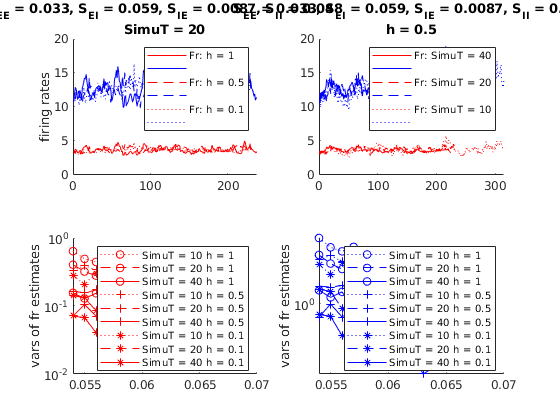

figure('Name','Compare hs/SimuTs for single trajectories')
% Same SimuT, different h
subplot 221
StestInd = 6; SimuTInd = 2;
LineType = {'-','--',':'};
hold on
for hInd = 1:b
plot(Fr_NoFixTraj_h_time{StestInd,hInd,SimuTInd}(1,:),'r','LineStyle',LineType{hInd},...
                                                          'DisplayName',['Fr: h = ' num2str(htest(hInd))])
plot(Fr_NoFixTraj_h_time{StestInd,hInd,SimuTInd}(2,:),'b','LineStyle',LineType{hInd},...
                                                          'DisplayName','')
end
hold off
title({['S_{EE} = ' num2str(S_EE) ', S_{EI} = ' num2str(S_EItest(StestInd)) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II)],...
                                       ['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3)]})
legend                                   
ylabel('firing rates')                  

% Same h, different SimuT
subplot 222
StestInd = 6; hInd = 2;
LineType = {'-','--',':'};
hold on
for SimuTInd = 1:c
plot(Fr_NoFixTraj_h_time{StestInd,hInd,SimuTInd}(1,:),'r','LineStyle',LineType{SimuTInd},...
                                                          'DisplayName',['Fr: SimuT = ' num2str(SimuTtest(SimuTInd)/1e3)])
plot(Fr_NoFixTraj_h_time{StestInd,hInd,SimuTInd}(2,:),'b','LineStyle',LineType{SimuTInd},...
                                                          'DisplayName','')
end
hold off
title({['S_{EE} = ' num2str(S_EE) ', S_{EI} = ' num2str(S_EItest(StestInd)) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II)],...
                                       ['h = ' num2str(htest(hInd))]})
legend


%varQuot1 = Fr_NoFixVar_h/Fr_NoFixVar; 
subplot(2,2,3)
LineType = {'-','--',':'};
MarkerType = {'o','+','*'};
hold on
for hInd = 1:b
    for SimuTInd = c:-1:1
        plot(S_EItest,Fr_NoFixVar_h_time(1,:,hInd,SimuTInd),'r',...
             'LineStyle',LineType{SimuTInd}, 'Marker',MarkerType{hInd},...
             'DisplayName',['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3) ' h = ' num2str(htest(hInd))])
    end
end
hold off
legend
set(gca,'YScale','log')
ylabel('vars of fr estimates')

subplot(2,2,4)
LineType = {'-','--',':'};
MarkerType = {'o','+','*'};
hold on
for hInd = 1:b
    for SimuTInd = c:-1:1
        plot(S_EItest,Fr_NoFixVar_h_time(2,:,hInd,SimuTInd),'b',...
             'LineStyle',LineType{SimuTInd}, 'Marker',MarkerType{hInd},...
             'DisplayName',['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3) ' h = ' num2str(htest(hInd))])
    end
end
hold off
legend
set(gca,'YScale','log')
ylabel('vars of fr estimates')